clear all;
load impulse_responses.mat
warning('off');


fs=16000;
num_samples=500000;
num_interferers=3;

[clean_speech,~] = audioread('clean_speech.wav');

[babble, ~] = audioread('babble_noise.wav');
[clean_speech_2, ~] = audioread('clean_speech_2.wav');
[artificial_nonstat_noise, ~] = audioread('aritificial_nonstat_noise.wav');

clean_speech = clean_speech(1:num_samples);
interference=[clean_speech_2(1:num_samples) babble(1:num_samples) artificial_nonstat_noise(1:num_samples)].';
clean_speech_energy=sum(clean_speech.^2);
for i =1:size(interference,1)
    interference(i,:)=norm_sig(interference(i,:),clean_speech_energy);
end


M=4; % Number of microphones
sigma = 0.1; % Variance of the white noise
%read in impulse responses
H = load('impulse_responses.mat');
h_target=getImpulse(H,5);
H_values=zeros(3,4,400);
H_values(1,:,:)=getImpulse(H,1);
H_values(2,:,:)=getImpulse(H,2);
H_values(3,:,:)=getImpulse(H,3);


%construct multiple sound_sources
x_time = zeros(4, num_samples+399);
s_time = zeros(4, num_samples+399); 
in_time=zeros(4, num_samples+399);

%speech2,babble, artificial, white
interference_ratio=[1,1,1,0];
SNR_mic_before = zeros(1, 4);
max_SNR=-10;
SNR_factor=0;

for i = 1:M
    target_signal=conv(clean_speech,h_target(i,:));

    %add white noise
    noise_inter = (randn(size(target_signal))*interference_ratio(4));
    for j=1:num_interferers
        interferer=conv(interference(j,:),squeeze(H_values(j,i,:)))*interference_ratio(j);
        noise_inter=noise_inter+interferer.';
    end
    if i==1
        SNR_factor=sqrt(sum(target_signal.^2)/(10^(max_SNR/10)*sum(noise_inter.^2)));
    end
    noise_inter=noise_inter*SNR_factor;
    signal=target_signal+noise_inter;
    x_time(i,:) = signal;
    s_time(i,:) = target_signal;
    in_time(i,:)=noise_inter;
    
    % Calculate the SNR
    SNR_mic_before(i) = 10 * log10(sum(abs(target_signal).^2) / sum(abs(signal - target_signal).^2));
    filename = sprintf('microphone%d.wav', i);
    audiowrite(filename, signal, fs);
end

 SNR_mic_before

SNR_mic_before =   -10.0000  -15.1116  -20.1656  -17.0507


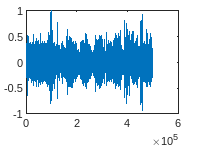

 figure;
 max_x=max(x_time(1,:));
 x_time=x_time/max_x;
plot(x_time(1,:))

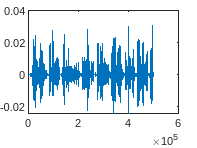


 figure;
 plot(s_time(1,:))

% Short time fourier transform
window_time=0.02;
% L = 2^nextpow2(window_time*fs);
L=window_time*fs;
Overlap=0.5;
[x_f,K] = s_t_f_t(x_time,L,Overlap);
x_f_vad=s_t_f_t(s_time(1,:)/max(s_time(1,:)),L,Overlap);
%add spatially white noise
for k =1:K
    x_f(:,k,:)=squeeze(x_f(:,k,:))+0.0025*(randn([M,L])+randi([M,L]))/sqrt(2);
end 
[n_f,~] = s_t_f_t(in_time,L,Overlap);






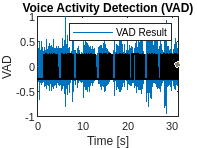

% Perform VAD
threshold=0.005;

vadResult = vad(x_f_vad, threshold);

% Time axis for the original signal
time = (0:length(x_time)-1) / fs;

% Time axis for the VAD result
D = round(L * (1 - Overlap));  % Step size
t_vad = (0:K-1) * D / fs;


% Plotting
figure;

% Plot the original signal

plot(time, x_time(1,:));
xlabel('Time [s]');
ylabel('Amplitude');
legend('Audio Signal');
hold on;
% Plot the binary VAD result

plot(t_vad, (vadResult-0.5)*0.5, 'k', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('VAD');
title('Voice Activity Detection (VAD)');

legend('VAD Result');
hold off;

S_est = zeros(1, K, L);
R_x=zeros([4,4]);
R_n=zeros([4,4]);
R_x_tilde=zeros([4,4]);
alpha=0.1;


for k = 1:K
    for l = 1:L
      curr_x=squeeze(x_f(:, k, l));

      if l==1
      R_n= curr_x*curr_x';
      R_x= curr_x*curr_x';
      else
              if vadResult(k)==0
                    R_n = alpha.*R_x + (1-alpha).*curr_x*curr_x';            
              end
            R_x = alpha.*R_x + (1-alpha).*curr_x*curr_x';
      end

      %now to estimate the atf
        [U,V]=eig(R_x,R_n);
        % Extract eigenvalues
        eigenvalues = diag(V);
        [V_sorted, sortedIndices] = sort(eigenvalues, 'descend');
        U_sorted = U(:, sortedIndices);
        a=U_sorted(:,1);


        R_x_inv=pinv(R_x);
        %calculate the RTF
        a=a/a(1);
        w = (R_x_inv *a ) / (a'*R_x_inv * a);
        % % %MVDR beamformer
        % R_x_inv = inv(reshape(R_x(l, :,:),[4,4]));
        % w = R_x_inv * a / (a' * R_x_inv * a);
        % w(isinf(w))=1;
        S_est(1, k, l) = w' * curr_x;
    end
end


%%

alpha = 0.2;
Rx = zeros(M, M);
Rn = zeros(M, M);
S = zeros(K, L);
mu = 0.5; 
for k = 1:K
    for l = 1:L
        if l==1
            vec_x = squeeze(x_f(:, k, l));
            Rx = vec_x(:)*vec_x(:)';
            Rn = vec_x(:)*vec_x(:)';
        else
            vec_x =  squeeze(x_f(:, k, l));
            Rx = alpha*Rx + (1-alpha)* vec_x(:)*vec_x(:)';
            if vadResult(l) == 0
                Rn = alpha*Rn + (1-alpha)* vec_x(:)*vec_x(:)';
            else
                Rn = Rn_prev;
            end
        end
        [a,sigma_s] = estimate_a(Rx, Rn);

        % Multi channel
        %inv_R = pinv(Rn);
        %w = (sigma_s*inv_Rn*a)/(sigma_s*(a'*inv_Rn*a)+mu);

        % MVDR
        %inv_R = pinv(Rx);
        % w = (inv_R *a ) / (a'*inv_R * a);

        % signal distortion weighted
        e = [1;0;0;0];
        Rs = sigma_s* a * a'; 
        w = (Rs + mu*Rn)\ Rs *e;

        S(k,l) = w'*vec_x(:); 
        Rn_prev= Rn; 
    end
end

% Inverse STFT to get the time-domain signal
S_est=reshape(S,[1,size(S,1),size(S,2)]);
s_est = i_s_t_f_t(S_est, L, Overlap);
s_est=s_est/max(s_est)

s_est =     0.0032    0.0012   -0.0011    0.0011   -0.0018   -0.0028    0.0015   -0.0009   -0.0001    0.0013    0.0008    0.0011    0.0011    0.0031   -0.0007   -0.0008    0.0015   -0.0022   -0.0018    0.0006   -0.0018   -0.0014    0.0002   -0.0003   -0.0012   -0.0012   -0.0010   -0.0020   -0.0017   -0.0017   -0.0017   -0.0014   -0.0011   -0.0013   -0.0007   -0.0001   -0.0006   -0.0003    0.0003    0.0003    0.0008    0.0008    0.0013    0.0024    0.0003    0.0000    0.0015    0.0003   -0.0012    0.0007


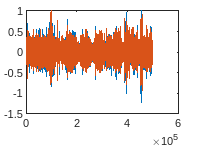

plot(s_est);
hold on;
plot(x_time(1,:));

hold off;

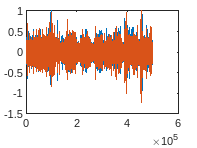



plot(x_time(1,:));
hold on;
plot(s_est);
hold off;



audiowrite('beamformed_output.wav', s_est, fs);
stoi(s_time(1,1:length(s_est)),real(s_est),16000)

ans = 0.9969

stoi(s_time(1,:),x_time(1,:),16000)

ans = 0.3931


% Inverse STFT to get the time-domain signal
output_signal = i_s_t_f_t(S_est, L, Overlapp);
plot(real(output_signal))
10 * log10(sum(clean_mic(1,1:500000).^2) / sum((output_signal(1:500000) - clean_mic(1,1:500000)).^2))


function H = getImpulse(impulse_response,index)    
    % Access the element from the struct
    impulses = reshape(struct2array(impulse_response), 5, 4, 400);
    H = squeeze(impulses(index,:,:));
end
function signal_out = norm_sig(in_signal,target_energy)
    factor= sqrt(target_energy/sum(in_signal.^2));
    signal_out = in_signal *factor;
end

function [a_hat, sigma_s] = estimate_a(Rx, Rn)
[~,D,Q] = eig(Rx, Rn);
eig_vals = spdiags(D);
[eig_vals_sorted, ind] = sort(eig_vals, 'descend');
a_hat = Q(:,ind(1));
% Rs_hat = a_hat*(D(1,1)-1)*a_hat';
sigma_s = eig_vals_sorted(1)-1;
end